## Number of Engagements/Kills

option		= "All options";

sheetName	= "blue_killed_by_red_system";
dataVar		= "Absolute";
data		= importData(sheetName, option, fullfile("data", "system_kills_31_03_2021.xlsx"));

statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"]); % Sum over blue systems and position
statarray.Properties.VariableNames{end} = char(dataVar);

grpVar		= ["Scenario"; "RedSystem"];
grpHeatmap(statarray, grpVar, dataVar, option, "AbsoluteKillNumberRedByScenarioByRedSystem", "Absolute kill number red");

## Fraction of Inside/Outside

statarray	= rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "RedSystem"; "ShooterLocation"]); % Sum over blue systems
statarray.Properties.VariableNames{end} = char(dataVar);

statarrayIn = statarray(statarray.ShooterLocation == "INSIDE", [1:3, 6]);
statarrayOut = statarray(statarray.ShooterLocation == "OUTSIDE", [1:3, 6]);


% Join tables
joinedData = innerjoin(statarrayIn,statarrayOut,"Keys",["Assessment",...
    "Scenario","RedSystem"])

joinedData = 950×5 table
                    Assessment                     Scenario                  RedSystem                   Absolute_statarrayIn    Absolute_statarrayOut
    ___________________________________________    ________    ______________________________________    ____________________    _____________________

    "Bodluv (regiment NO GR, limited mobility)"    "Regio"     "Air Defence Gun"                                21.49                     1.14        
    "Bodluv (regiment NO GR, limited mobility)"    "Regio"     "Artillery Wheeled"                               2.01                    17.21        
    "Bodluv (regiment NO GR, limited mobility)"    "Regio"     "Inf Squad LMG / AT4 / Javelin"                   8.25                     0.52        
    "Bodluv (regiment NO GR, limited mobility)"  

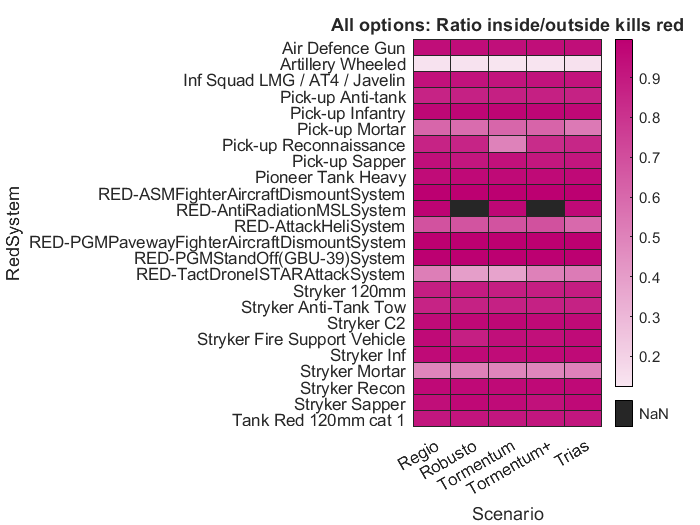

joinedData.("RatioInOut") = joinedData.Absolute_statarrayIn./(joinedData.Absolute_statarrayIn+joinedData.Absolute_statarrayOut);
grpVar		= ["Scenario"; "RedSystem"];
grpHeatmap(joinedData, grpVar, "RatioInOut", option, "RatioInTotalKillRedByScenarioByRedSystem", "Ratio inside/total kills red");